# Evaluating the Average Power Delivered by a Wind Turbine

This example uses Symbolic Math Toolbox and the Statistics and Machine Learning Toolbox to explore and derive a parametric analytical expression for the average power generated by a wind turbine.

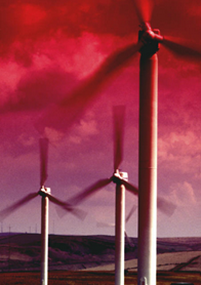

The parametric equation can be used for evaluating various wind turbine configurations and wind farm sites. More information see [Wind Resource Assessment](https://www.mathworks.com/discovery/wind-resource-assessment.html).

**Background**

The total power delivered to a wind turbine can be estimated by taking the derivative of the wind's kinetic energy. This results in the following expression:

         $P_w =\frac{\rho {\;A\;u}^3 }{2}$     (1)

- A is the swept area of turbine blades, in $m^2$

- ρ = air density, in $\textrm{kg}/m^3$

- u = wind speed, in $m/s$

The process of converting wind power to electrical power results in efficiency losses, as described in the diagram below.

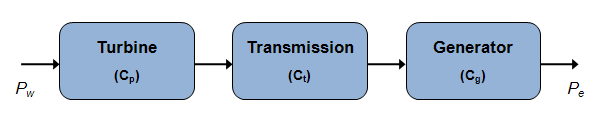

The electrical power output of a practical wind turbine can be described using the following equation:

$P_e =\frac{C_{\textrm{tot}} \;\;\rho {\;\textrm{Au}}^3 }{2}$   (2)    where $C_{\textrm{tot}} =\textrm{overall}\;\textrm{efficiency}=C_p C_t C_g$

The overall efficiency is between 0.3 and 0.5, and varies with both wind speed and rotational speed of the turbine. For a fixed rotational speed, there is a rated wind speed at which electrical power generated by the wind turbine is near its maximum ($P_{\textrm{er}}$), and overall efficiency at this point is denoted $C_{\textrm{totR}}$.

$P_{\textrm{er}} =\frac{C_{\textrm{totR}} \;\;\rho {\;\textrm{Au}}^3 }{2}$   (3) 

Assuming a fixed rotational speed, the electrical power output of the wind turbine can be estimated using the following profile:

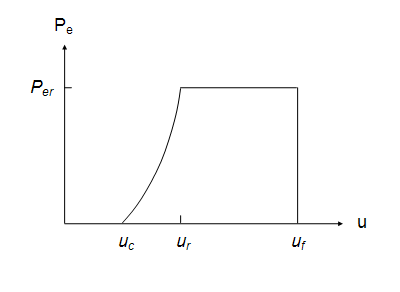

Where

- $u_r$ = rated wind speed

- $u_c$ = cut-in speed, the speed at which the electrical power output rises above zero and power production starts

- $u_f$ = furling wind speed, the speed at which the turbine is shut down to prevent structural damage

As seen in the figure, we assume that output power increases between $u_c$ and $u_r$, then is at a constant maximum value between $u_r$ and $u_f$. Power output is zero for all other conditions.

## **Derive Equation for Average Power of Wind Turbine**

## I. Define piecewise expression for power

We define a piecewise function that described turbine power.

syms Per C_1 C_2 k u u_c u_f u_r 
Pe = piecewise(u < u_c, 0, u_c <= u <= u_r, C_1 + C_2 * u^k, (u_r <= u) <= u_f, Per, u_f < u, 0)

Where variables $C_1$ and $C_2$ are defined as follows:

C_1 = (Per * u_c^k)/(u_c^k - u_r^k)
C_2 = Per/(u_r^k - u_c^k)

## **II. Define external wind conditions**

The rated power output offers a good indication of a how much power a wind turbine is capable of producing, however we'd like to estimate how much power (on average) the wind turbine will actually deliver. To calculate average power, we need to account for external wind conditions. A Weibull distribution does a good job at modeling the variance in wind, therefore the wind profile can be estimated using the following probability density function:

 $f\left(u\right)=\frac{\left(\frac{b}{a}\right)\,{\left(\frac{u}{a}\right)}^{b-1} }{{\mathrm{e}}^{{\left(\frac{u}{a}\right)}^b } }$    (4)

In general, larger 'a' values indicate a higher median wind speed, and larger 'b' values indicate reduced variability. 

We use the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/help/stats/weibull-distribution.html) to generate a Weibull distribution and illustrate the variability in wind at our wind farm site (a=12.5, b=2.2):

a = 12.5;
b = 2.2;
N = 1000;
pd = makedist('Weibull','a',a,'b',b)     
r = wblrnd(a,b,[1 N])
x = linspace(0,34,N);
y = pdf(pd,x);
plot(x,y,'LineWidth',2)
hold on 
histogram(r,15,'Normalization','pdf')
hold off
title('Weibull Distribution of Wind Speeds')
xlabel('Wind Speed (m/s)')

## **III. Calculate average power**

The average power output from a wind turbine can be obtained using the following integral:

 $Pe_{average} =\int_0^{\infty } Pe(u)\,f(u)du$ (5)

Power is zero when wind speed is less than the cut in wind speed $u_c$ and greater than furling wind speed $u_f$. Therefore, the integral can be expressed as follows:

 $Pe_{average} =C_1 \,\left(\int_{u_c }^{u_r } f\left(u\right)\,du\right)+C_2 \,\left(\int_{u_c }^{u_r } u^b f\left(u\right)du\right)+\mathrm{P}\mathrm{e}\mathrm{r}\,\left(\int_{u_r }^{u_f } f\left(u\right)\,du\right)$ (6)

There are two distinct integrals in equation (7). We plug equation (4) into these integrals and simplify them using the substitutions: $x={\left(\frac{u}{a}\right)}^b$ and $\mathrm{d}\mathrm{x}=\left(\frac{b}{a}\right)\,{\left(\frac{u}{a}\right)}^{b-1} \,\mathrm{d}\mathrm{u}$. This simplifies our original integrals to the following:

  $\int f\left(u\right)\,du=\int \frac{1}{{\mathrm{e}}^x }\,dx$    (7)

 $\int u^b \,f\left(u\right)\,du=a^b \,\left(\int \frac{x}{{\mathrm{e}}^x }\,dx\right)$    (8)

Solving these integrals and then replacing x with ${\left(\frac{u}{a}\right)}^b$  yields:

syms a b x
int1 = int(exp(-x), x);
int1 = subs(int1, x, (u/a)^b)

int2 = int(x * exp(-x) * a^b, x);
int2 = subs(int2, x, (u/a)^b)

Substituting the results into equation (6) yields an equation for average power output of the wind turbine.

Peavg = subs(C_1 * int1, u, u_r) - subs(C_1 * int1, u, u_c) + subs(C_2 * int2, u, u_r) - subs(C_2 * int2, u, u_c) + subs(Per * int1, u, u_f) - subs(Per * int1, u, u_r)

## IV. Conclusion

We have used the Symbolic Math Toolbox to develop a parametric equation which can be used to perform simulation studies to determine the average power generated for various wind turbine configurations and wind farm sites.

*Copyright 2016 The MathWorks, Inc.*